# **Aplicación de métodos numéricos a un modelo SIRV**

**Modelo SIRV:**


$$\frac{ds}{dt} = -\beta si - \delta s\\
\frac{di}{dt} = \beta si - \gamma i\\
\frac{dr}{dt} = \gamma i\\
\frac{dv}{dt} = \delta s$$


**Supuestos:** población cerrada (no llegan personas de otros lugares) y constante ($s+ i+ r+ v= 1$), población uniforme, mezcla homogénea (sin consideraciones de edad, distribución espacial, educación o estructura social).

**Variables:**

    $s:$ porcentaje de personas susceptibles (pueden contraer la enfermedad)

    $i:$ porcentaje de personas infectadas

    $r:$ porcentaje de personas recuperadas (y que no vuelven a contraer la enfermedad, es decir, quedan inmunes) 

    $v:$ porcentaje de personas vacunadas.

**Parámetros:**

    $\beta:$ tasa de transmisión

    $\gamma :$ tasa de recuperación

    $\delta :$ tasa de vacunación

Observar que se tiene una epidemia creciente si (igual que en el caso SIR):

    
$$\frac{di}{dt} = (\beta s -\gamma)i>0$$


    
$$R_0 = \frac{\beta s(0)}{\gamma} $$
   

Note que hay epidemia si $R_0> 1$ 

**Caso de estudio:** 

    
$$\beta = 0.1$$


    
$$\gamma = 0.02$$


    
$$\delta = 0.001$$


    
$$s(0) = 0.8$$


    
$$i(0) = 0.1$$


    
$$r(0) = 0$$


    
$$v(0) = 0.1$$


## 1. Solución numérica del modelo con pico epidémico

#### Cálculo numérico con las condiciones iniciales y parámetros dados

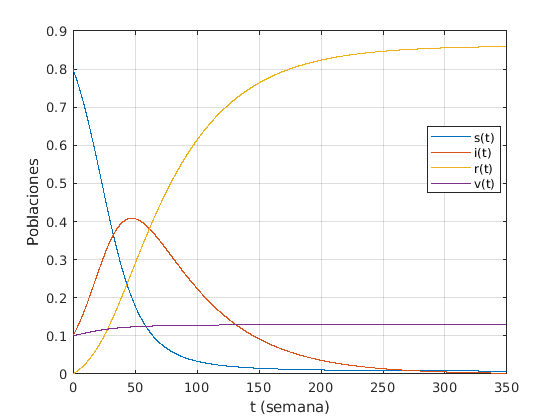

syms s(t) i(t) r(t) v(t)

% Parametros
beta = 0.1; gamma = 0.02; delta= 0.001;

% Ecuaciones
f1 = -beta*s*i - delta*s;
f2 = beta*s*i - gamma*i;
f3 = gamma*i;
f4 = delta*s;
f = odeFunction([f1 f2 f3 f4],[s i r v]); 

% Metodo numerico
h = 0.1;
tmin = 0;
tmax = 350;
tspan = tmin:h:tmax;

% Condiciones iniciales
ci = [0.8 0.1 0 0.1]; 

% solucion método numérico 
[t1,X1] = ode45(f,tspan,ci);
plot(t1,X1)
xlabel('t (semana)')
ylabel('Poblaciones')
grid on
legend({'s(t)','i(t)','r(t)','v(t)'}, 'Location','best')

#### Cálculo numérico cambiando v(0)

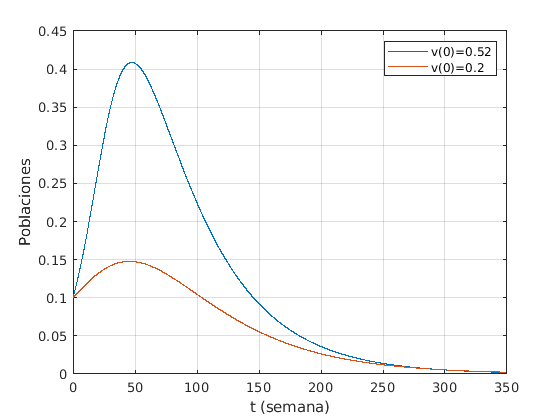

v0 = 0.52; 
ci = [0.9-v0 0.1 0 v0]; 
[t2,X2] = ode45(f,tspan,ci);
plot(t1,X1(:,2),t2,X2(:,2))
xlabel('t (semana)')
ylabel('Poblaciones')
grid on
legend({['v(0)=' num2str(v0)],'v(0)=0.2'})

## 2. Soluciones numéricas con un cambio de i(0)

Observar el efecto negativo al tener inicialmente una población mayor de personas infectadas.

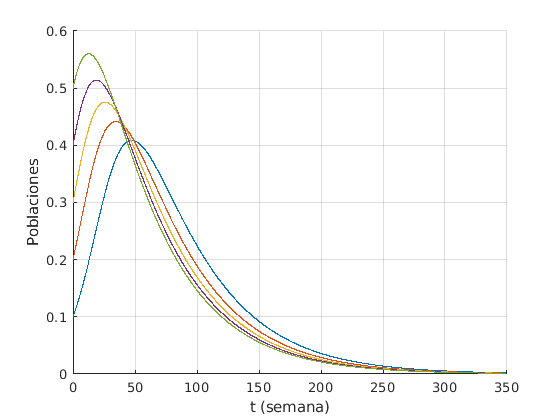

syms s(t) i(t) r(t) v(t)

% Parametros
beta = 0.1; gamma = 0.02; delta= 0.001;

% Ecuaciones
f1 = -beta*s*i - delta*s;
f2 = beta*s*i - gamma*i;
f3 = gamma*i;
f4 = delta*s;
f = odeFunction([f1 f2 f3 f4],[s i r v]); 

% Metodo numerico
h = 0.1;
tmin = 0;
tmax = 350;
tspan = tmin:h:tmax;

% Condiciones iniciales
MultipleCI = [0.8 0.1 0 0.1
              0.7 0.2 0 0.1
              0.6 0.3 0 0.1
              0.5 0.4 0 0.1
              0.4 0.5 0 0.1];

% solucion método numérico 
figure
for k = 1:length(MultipleCI)
    [t,x] = ode45(f,tspan,MultipleCI(k,:));
    hold on
    plot(t,x(:,2))
    xlabel('t (semana)')
    ylabel('Poblaciones')
    grid on
end

## 3. Soluciones numéricas con un cambio de $\beta$

Observar el efecto positivo de disminuir $\beta$ (tasa de transmisión)

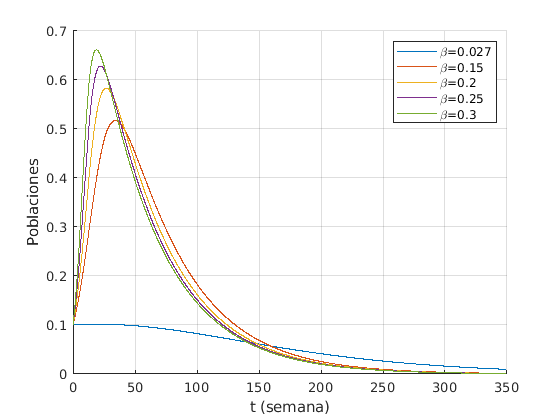

syms s(t) i(t) r(t) v(t)

% Parametros
beta = [0.027 0.15 0.20 0.25 0.30]; 
gamma = 0.02; 
delta= 0.001;

% Ecuaciones
f3 = gamma*i;
f4 = delta*s;

% Metodo numerico
h = 0.1;
tmin = 0;
tmax = 350;
tspan = tmin:h:tmax;

% Condiciones iniciales
ci = [0.8 0.1 0 0.1];

% solucion método numérico 
figure
for k = 1:length(beta)
    f1 = -beta(k)*s*i - delta*s;
    f2 = beta(k)*s*i - gamma*i;
    f = odeFunction([f1 f2 f3 f4],[s i r v]); 
    [t,x] = ode45(f,tspan,ci);
    hold on
    plot(t,x(:,2))
    xlabel('t (semana)')
    ylabel('Poblaciones')
    grid on
end
legend({'\beta=0.027','\beta=0.15','\beta=0.2','\beta=0.25','\beta=0.3'})

## 4. Soluciones numéricas con un cambio de $\gamma$

Observar el efecto positivo de aumentar $\gamma$ (tasa de recuperación)

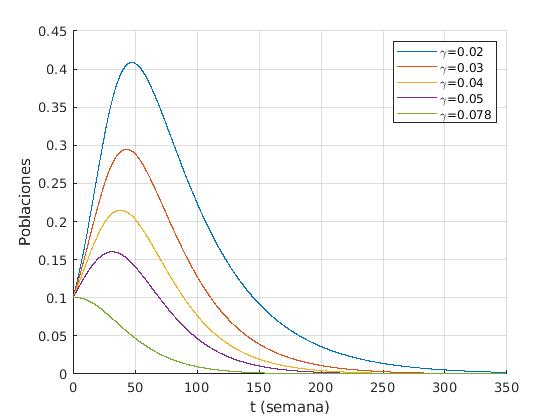

syms s(t) i(t) r(t) v(t)

% Parametros
beta = 0.1; 
gamma = [0.02 0.03 0.04 0.05 0.078]; 
delta= 0.001;

% Ecuaciones
f1 = -beta*s*i - delta*s;
f4 = delta*s;

% Metodo numerico
h = 0.1;
tmin = 0;
tmax = 350;
tspan = tmin:h:tmax;

% Condiciones iniciales
ci = [0.8 0.1 0 0.1];

% solucion método numérico 
figure
for k = 1:length(gamma)
    f2 = beta*s*i - gamma(k)*i;
    f3 = gamma(k)*i;
    f = odeFunction([f1 f2 f3 f4],[s i r v]); 
    [t,x] = ode45(f,tspan,ci);
    hold on
    plot(t,x(:,2))
    xlabel('t (semana)')
    ylabel('Poblaciones')
    grid on
end
legend({'\gamma=0.02','\gamma=0.03','\gamma=0.04','\gamma=0.05','\gamma=0.078'})

## 5. Soluciones numéricas con un cambio de $\delta$

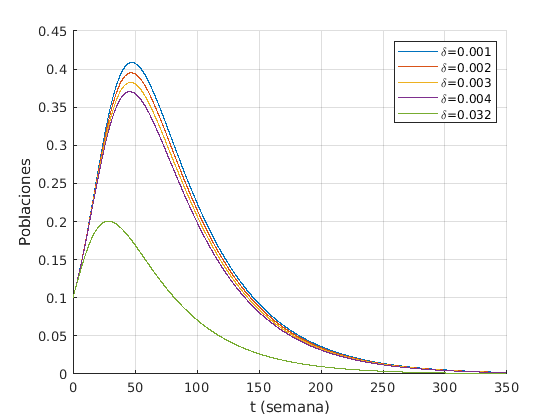

syms s(t) i(t) r(t) v(t)

% Parametros
beta = 0.1; 
gamma = 0.02; 
delta= [0.001 0.002 0.003 0.004 0.032];

% Ecuaciones

f2 = beta*s*i - gamma*i;
f3 = gamma*i;

% Metodo numerico
h = 0.1;
tmin = 0;
tmax = 350;
tspan = tmin:h:tmax;

% Condiciones iniciales
ci = [0.8 0.1 0 0.1];

% solucion método numérico 
figure
for k = 1:length(delta)
    f1 = -beta*s*i - delta(k)*s;
    f4 = delta(k)*s;
    f = odeFunction([f1 f2 f3 f4],[s i r v]); 
    [t,x] = ode45(f,tspan,ci);
    hold on
    plot(t,x(:,2))
    xlabel('t (semana)')
    ylabel('Poblaciones')
    grid on
end
legend({'\delta=0.001','\delta=0.002','\delta=0.003','\delta=0.004','\delta=0.032'})